# MPO 634 - Assignment 02 Spring 2020              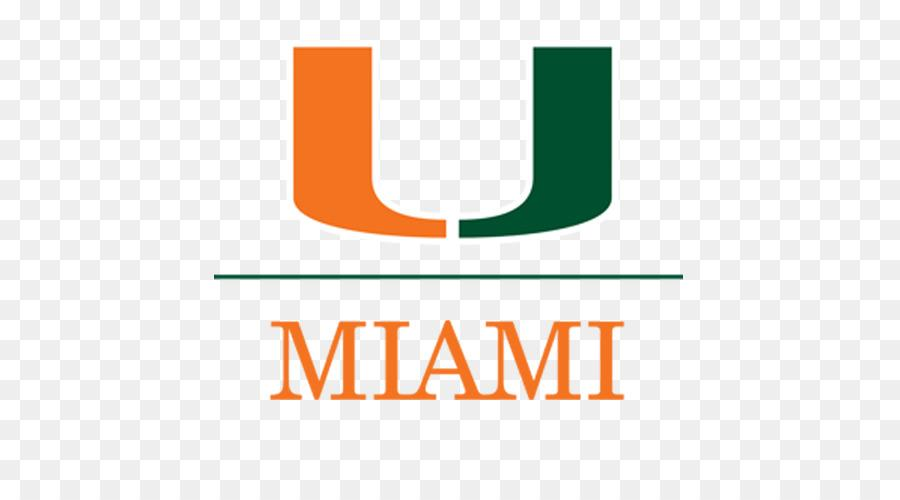

## Ivenis Pita

See slide 32 in lecture lec09 [here](http://www.ldeo.columbia.edu/users/menke/edawm/eda_lectures/). This is based on Ch. 6 of this [e-book](https://miami-primo.hosted.exlibrisgroup.com/primo-explore/fulldisplay?docid=01UOML_ALMA51300698040002976&context=L&vid=uml_new&lang=en_US&search_scope=default_scope&adaptor=Local%20Search%20Engine&isFrbr=true&tab=default_tab&query=any,contains,environmental%20data%20analysis&sortby=date&facet=frbrgroupid,include,615420309&offset=0), if you want to read a text about it.

#### 1- Write the **G** matrix in slide 32 with just 4 columns: the mean, a trend, and the seasonal cycle (sine and cosine components, most easily interpreted if you use a solstice as t=0).

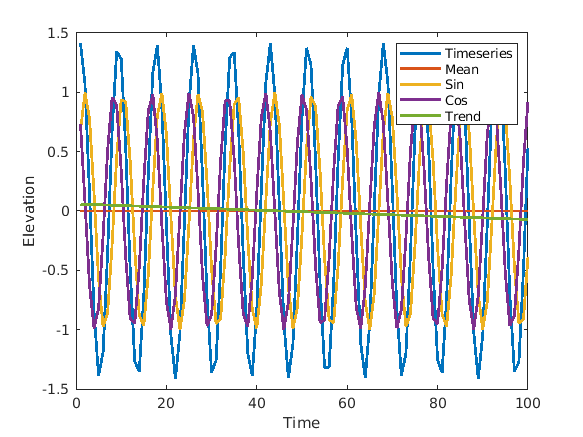

clear variables
close all
clc

w1=.75;%frequency 1
w2=.75;%frequency 2
t=(1:100)';%time [hours]
G=[0*ones(size(t)),sin(w1*t),cos(w2*t)];%G[mean,seasonal 1, seasonal 2]
G_tot=G(:,1)+G(:,2)+G(:,3); %time series with all frequencies + mean

%Caclulating trend
b = polyfit(t,G_tot, 1);
G(:,4) = polyval(b, t); %G[mean, seasonal 1, seasonal 2, trend]
plot(G_tot,'linewidth',2),hold on, plot(G,'linewidth',2),legend('Timeseries','Mean','Sin','Cos','Trend')

xlabel('Time')
ylabel('Elevation')

#### 2- What is the variance of a linear trend with range M over a time interval? The trend goes from -M/2 to M/2 in the time interval [0,T]. To answer, sketch it, square it, and average that over the interval to get the variance in terms of M.

%calculate M
M=-G(1,4)/2;
%Variance of the trend
var_M=sum((G(:,4)-nanmean(G(:,4))).^2)/max(t);

#### 3- What is the variance of a sinusioidal wave of amplitude A? To answer, square and average sin() or cos() functions over the interval [0,]. Hint: it helps to remember that , and note that the variance of sin and cos are equal.

%Variance of the trend
%in this case A=1;
var_sin=sum((G(:,2)-nanmean(G(:,2))).^2)/max(t);
var_cos=sum((G(:,3)-nanmean(G(:,3))).^2)/max(t);

#### 4- Since the column of ones captures the mean value of the time series **d**, the trend term needs a form like . What is the needed form of that  for a gappy data record? Is it the true average of t over the time interval spanned by the data, or the simple average of t for all the available times? Explain.

Ivenis, might you be able to use the Matlab code of problem eda06_02.m in the supplemental code .zip file at [this site](https://www.ldeo.columbia.edu/users/menke/edawm/) to do the above exercise: fitting your data as a mean, seasonal cycle, and trend without any need for gap filling.